# MHKiT Tidal Example 

This notebook will familiarize the user with the mhkit tidal module by stepping through the calculation of the calculation of the velocity duration curve.

## Importing Data from NOAA-Currents 

This example will pull 1 year of data frooooom the NOAA-Currents site available sites can be viewed on the map Check the map for available currents stations [https://tidesandcurrents.noaa.gov/map/](https://tidesandcurrents.noaa.gov/map/). We will start by requesting 1 year of 6 minute averaged data from the Southampton Shoal Channel LB 6 (Station Number: s08010) in San Francisco Bay. The function request_noaa_data in the MHKit tidal IO module returns a Matlab structure. To use the request_noaa_data function we will need a station number, parameter type, a start date and an end date. The station ID can be found on the NOAA tides and currents website linked above. The IEC standard recommends 1 year of 10 minute direction and velocity data. The request_noaa_data function allows users to easily pull any timeframe of data although NOAA limits any one pull to 30 days.

% Create a file name to save the requested data to
currents_file = "data/s08010.json"; % South Hampton Shoal LB

% If the file already exists, load the data
if isfile(currents_file)
    data = read_noaa_json(currents_file);
% If the file is not found, request the data from NOAA and save as JSON
% with write_JSON optional parameter
else
    data = request_noaa_data("s08010","currents","20161101","20180401",currents_file);
end

% Convert discharge data from cm/s to m/s
data.s = data.s/100.; 

The request_noaa_data has returned a Matlab Structure of time series data between November of 2016 and March of 2018. The time series data points are 6 minute averaged direction [degrees] and speed [cm/s] data indexed by time. The structure key names returned by NOAA are 'd' for direction and 's' for speed. The speed returned from NOAA is in cm/s so we converted this to m/s. An initial data check may look at the timeseries data to identify how any missing data. To do this we will convert the speed data to velocity using the directional data. To choose a direction to calculate the velocity on we will use the `principal_flow_direction` function. This function returns 2 directions in degrees corresponding to the flood and ebb directions of the tidal site. From these two direction we can choose either as our principal flow direction. The `plot_current_timeseries` function then calculates velocity to the chosen direction for all speeds in the passed timeseries.

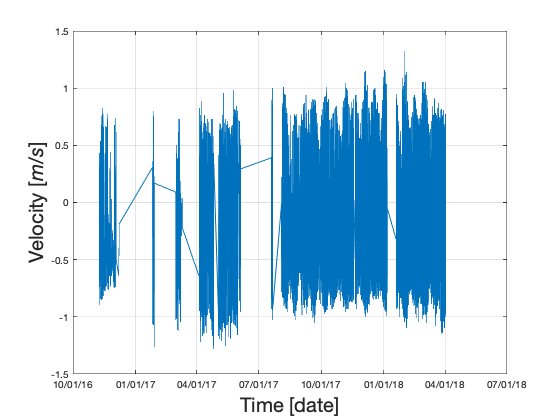

% We need to specify a histogram bin width for the directions to calculate
% the principal flow direction 
width_direction = 1; % [degrees]

% Two principal directions are calculated based on the highest frequency
% direction 
% One direction is the flood, the other is tide or ebb. 
% they are 180 degrees apart, but not required to be 
[direction1, direction2] = principal_flow_directions(data.d,width_direction);

% Set the flood and ebb directions based on site knowledge
flood = direction1 ; %flow into
ebb = direction2 ; % flow out

figure(1);
plot_current_timeseries(data,flood);

The plot above shows that the NOAA site request did not return data for most of early and mid 2017. The IEC standard reccomends a minimum of 1 year of 10 minute averaged data (See IEC 201 for full description). For the purposes of demonstration this dataset is suffcient. To look at a speficic month we can slice the dataset before passing to the plotting function.

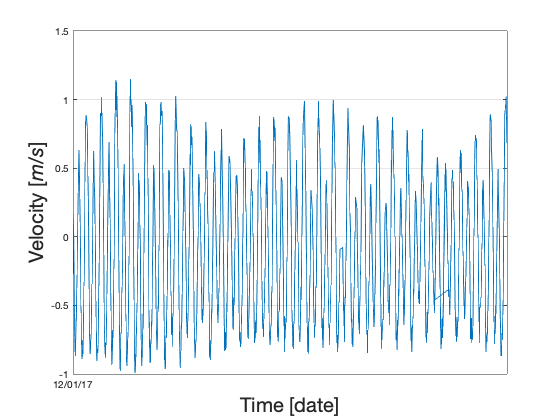

% Slice December of 2017 out of the full dataset 
start = posixtime(datetime('2017-12-01','InputFormat','yyyy-MM-dd'));
stop = posixtime(datetime('2017-12-31','InputFormat','yyyy-MM-dd'));
index = data.time > start & data.time < stop ; 
datadec.time = data.time(index);
datadec.s = data.s(index);
datadec.d = data.d(index);
figure(2);
plot_current_timeseries(datadec,flood);

## Plot the data as a joint probability distribution 

The data points may also be viewed as a joint porbabilty distribution of direction and velocity on a polar plot. This plot will help visually show the flood and ebb directions and the frequency of particular directions/ velocities.

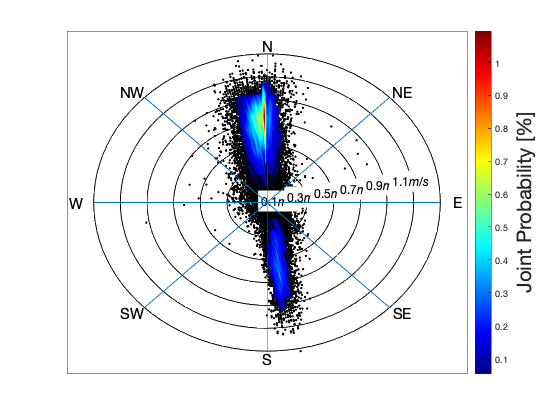

% Set the joint probability bit widths 
width_direction = 1 ;  %[degrees]
width_velocity  = 0.1 ; %[m/s]

% Plot the joint probability distribution
figure(3);
plot_joint_probability_distribution(data,width_direction,width_velocity);

## Plot the data as a rose plot

One additional polar plot of interest maybe the rose plot. This plot shows the same information as the joint probability distribution but the probability is now the r-axis, and the velocity is the contour value.

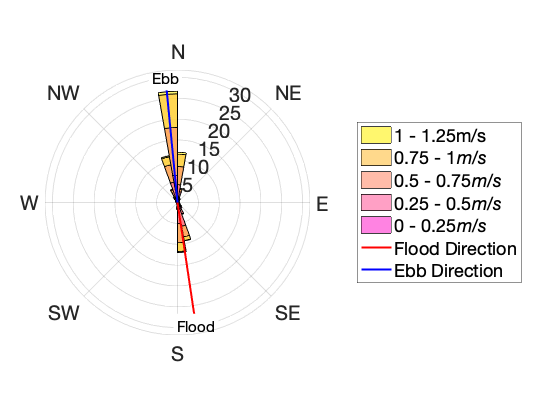

% A rose plot is more readable using larger bin sizes than the jpd plot
width_direction = 10; % [degrees]
width_velocity = 0.25; %[m/s]

%plot the rose plot
figure(4);
plot_rose(data,width_direction,width_velocity,[flood,ebb]); 

## Velocity Duration Curve

The velocity duration curve shows the probability of achiving a particular velocity value. This may be plotted by calculating the exceedance probability of the velocity (rank order velocity values).

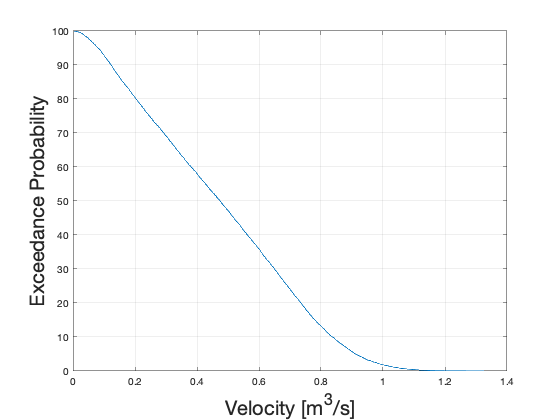

% Calculate teh exceedance probability of the data
data.Discharge = data.s; % need to change structure name for exceedance probability function
F = exceedance_probability(data);

% Plot the VDC
figure(5);
plot_velocity_duration_curve(data.s,F.F);